# Final Project Notebook

## By: Lorenzo Caseiro and Matthew Adams

## **Introduction**

    Glacial ice on the Earth can provide evidence of the state of the planet's past climatic conditions. Air can be trapped within the ice and act as a time capsule that records the atmospheric composition of times past. The air is trapped when continual snowfall buries it under deeper layers of snow until the layer eventually solidifies to ice under increased pressure. This is known as the "bubble closeoff depth" and it is the point at which the bubbles are fully formed and solidified within the ice (Bender et al 1997). The air bubbles provide evidence of certain trace gases, such as methane or carbon dioxide, and their concentration at the time the ice formed (Legend and Mayewski 1997).

    Many modern day researchers use these gas bubbles to measure past climate conditions, and it is invaluable in determining the anthropogenic changes to the Earth's climate. Much of the contmeporary study of this topic focuses on extracting ice cores from the glacial ice sheets that hold the trapped bubbles of air. The ice cores, and the gas bubbles within them, can be studied for paleoclimatologic and paleoceanographic purposes. However, this model, created using information from "Mathematical Modeling of earth's Dynamical Systems: A Primer", does not focus specifically on the results that ice cores can yield. Instead, it models an important consideration that is essential for obtiaing accurate results from the study of ice cores: diffusion of gas bubbles within glacial ice. Gas trapped in glacial ice can diffuse according to Fick's law, and this model seeks to follow how gas would diffuse within a given ice sheet (Singerland and Kump 2011). This information allows for proper tracking of gas within the ice and will yield more accurate results when reconstructing paleoclimate concentrations.

## **Equations**

## **Numerical Method**

% Define Parameters
CO2_solub = 2*10^(-6); %mol/(cm^3*ppm)
CO2_solub = CO2_solub/(1*10^(-6)); %mol/(m^3*ppm)
D = 1*10^(-7); %cm^2/s
D = D*3153.6; %m^2/yr
w = 0.1; %m/yr
t_final = 500; %yr

% Define Grid
delta_t = 0.005; %yr
t = 0:delta_t:t_final; %yr
n_t = length(t);

x_final = t_final*w; %m
delta_x = 1; %m
x = 0:delta_x:x_final+delta_x; %m
n_x = length(x);

C_num = w*delta_t/delta_x; %Courant Number
D_P = D*delta_t/(delta_x^2);

### Solve W/O Matrix

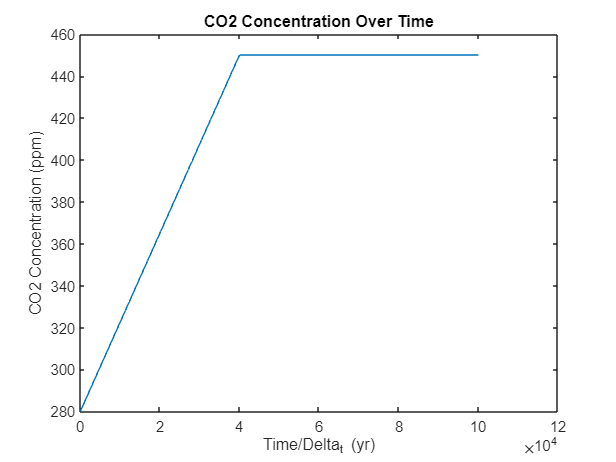

% Solve
C_pre1900 = 280; %ppm
C_post2100 = 450; %ppm
C_1900_2100 = linspace(C_pre1900, C_post2100, 200/delta_t); %ppm
for k = 1:(n_t-(200/delta_t))
    C_1900_2100(end+1) = C_post2100;
end

plot(C_1900_2100)
title('CO2 Concentration Over Time');
xlabel('Time/Delta_t (yr)'); ylabel('CO2 Concentration (ppm)')

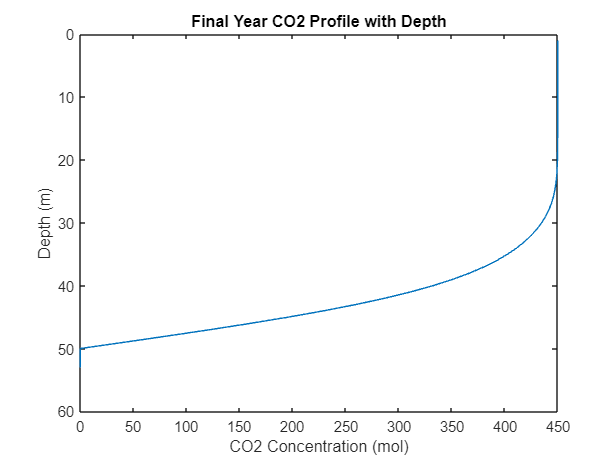


C = zeros(n_x+1,n_t);
C(1,:) = C_1900_2100;

% Prevent Snow from Diffusing into Grid Spaces too Soon
snow = zeros(n_x, n_t);
for k = 1:n_t
    for i = 1:n_x
        if (i - k*delta_t*w) == 0
            snow(i,k) = 2;
        end
        if (i - k*delta_t*w) < 0
            snow(i,k) = 1;
        end
    end
end

for k = 1:(n_t-1)
    for i = 2:(n_x-1)
        if snow(i,k) == 1 %Normal Advection Diffusion
            C(i,k+1) = C(i,k) - C_num*(C(i,k) - C(i-1,k)) + D_P*(C(i+1,k) - 2*C(i,k) + C(i-1,k));
        end
        if snow(i,k) == 2 %No flux boundary
            C(i,k+1) = C(i,k);
        end
        if snow(i,k) == 0 %Out of Snow Bounds
            C(i,k+1) = 0;
        end
    end
end


plot(C(:,end-1));
set(gca, 'XDir','reverse');
view([90 -90]);
xlabel('Depth (m)'); ylabel('CO2 Concentration (mol)');
title('Final Year CO2 Profile with Depth')

### Animation (Run at Own Risk)

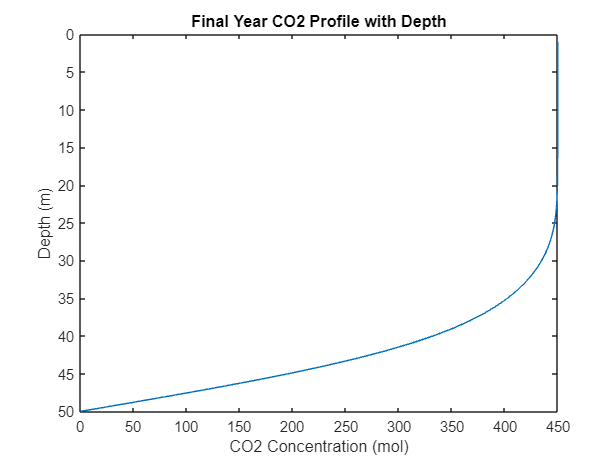

figure;
for i = 1:(n_t/100)
    plot(C(:,i*100))
    set(gca, 'XDir','reverse');
    view([90 -90]);
    xlabel('Depth (m)'); ylabel('CO2 Concentration (mol)');
    title('Final Year CO2 Profile with Depth')
    xlim([0 x_final]);
    ylim([0 max(C(:,end))]);
    drawnow
end

### Solve With Matrix (WIP)

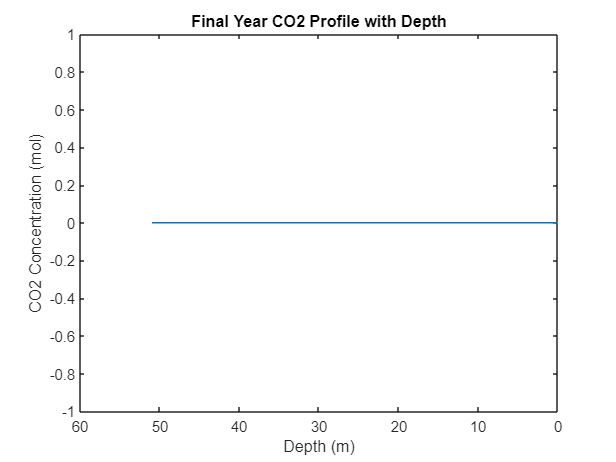

% Solve
C_pre1900 = 280; %ppm
C_post2100 = 450; %ppm
C_1900_2100 = linspace(C_pre1900, C_post2100, 200); %ppm
for k = 1:(n_t-200)
    C_1900_2100(end+1) = C_post2100;
end

C = zeros(n_x,n_t);

data_M = [(D_P + C_num)*ones(n_x,1), (1 - D_P - 2*C_num)*ones(n_x,1), C_num*ones(n_x,1)];
M = spdiags(data_M, -1:1, n_x, n_x);

for i = 2:(n_t - 1)
    C(:,i+1) = M\C(:,i);
end

% Plot
figure;
plot(x, C(:, end));
set(gca, 'XDir', 'reverse');
xlabel('Depth (m)');
ylabel('CO2 Concentration (mol)');
title('Final Year CO2 Profile with Depth');

## **Results**

## **Video Walkthrough**

## **References**

Bender, Michael, et al. “Gases in ice cores.” *Proceedings of the National Academy of Sciences*, vol. 94, no. 16, 1997, pp. 8343–8349, https://doi.org/10.1073/pnas.94.16.8343. 

Legrand, Michel, and Paul Mayewski. “Glaciochemistry of polar ice cores: A Review.” *Reviews of Geophysics*, vol. 35, no. 3, 1997, pp. 219–243, https://doi.org/10.1029/96rg03527. 

Slingerland, Rudy, and Lee R. Kump. “Advection and Diffusion (Transport) Problems.” *Mathematical Modeling of Earth’s Dynamical Systems: A Primer*, Princeton University Press, Princeton, 2011, pp. 124–125. 